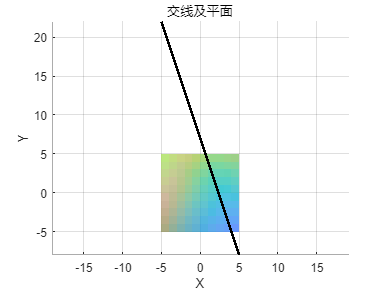

% 平面1的参数 (A1x + B1y + C1z + D1 = 0)
A1 = 1; B1 = 2; C1 = -1; D1 = -4;

% 平面2的参数 (A2x + B2y + C2z + D2 = 0)
A2 = 2; B2 = -1; C2 = 1; D2 = -3;

% 选择一个自由变量 (假设为 x)
syms x y z

% 方程1和方程2
eq1 = A1*x + B1*y + C1*z + D1 == 0;
eq2 = A2*x + B2*y + C2*z + D2 == 0;

% 解方程组
sol = solve([eq1, eq2], [y, z]);

% 提取解
y_sol = sol.y;
z_sol = sol.z;

% 设定 x 的范围
x_vals = linspace(-5, 5, 100);
y_vals = double(subs(y_sol, x, x_vals));
z_vals = double(subs(z_sol, x, x_vals));

% 绘图
figure;
hold on;
% 绘制平面1
[X1, Y1] = meshgrid(-5:1:5, -5:1:5);
Z1 = (-A1*X1 - B1*Y1 - D1) / C1;
surf(X1, Y1, Z1, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% 绘制平面2
[X2, Y2] = meshgrid(-5:1:5, -5:1:5);
Z2 = (-A2*X2 - B2*Y2 - D2) / C2;
surf(X2, Y2, Z2, 'FaceAlpha', 0.5, 'EdgeColor', 'none');

% 绘制交线
plot3(x_vals, y_vals, z_vals, 'LineWidth', 2, 'Color', 'k');

% 设置坐标轴
xlabel('X');
ylabel('Y');
zlabel('Z');
title('交线及平面');

axis equal;
grid on;
hold off;